# Image Segmentation

Segmentation is the process of locating items or regions of interest in an image.

## Otsuthreshold

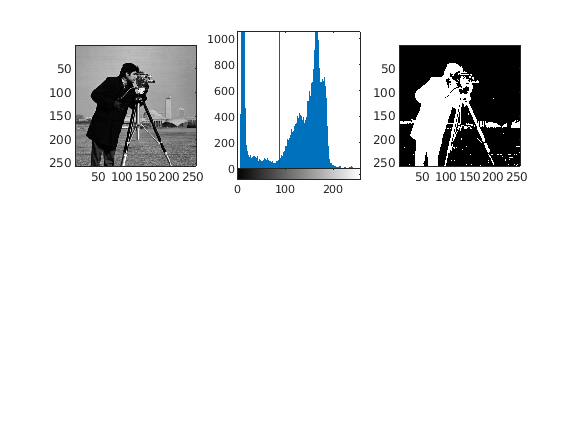

img = imread('cameraman.tif');
colormap('gray');
subplot(2,3,1);
imagesc(img);
axis tight equal;
subplot(2,3,2);
imhist(img);
hst = imhist(img);%return s histogram as a vector
thrsh = otsuthresh(hst); %range is 0 to 1
hold on;
plot(thrsh*255*[1,1],[0,1500], 'r');
hold off;
%Create the image mask for visual inspection
msk = img<thrsh*255;
subplot(2,3,3);
imagesc(msk);
axis tight equal;

## Using Filter to incorporate Spatial information

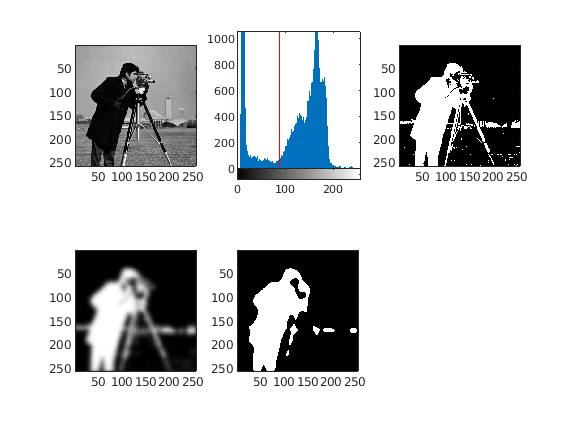

filt = fspecial('gaussian', [30 30], 5);
msk_filt = conv2(msk,filt,'same');
subplot(2,3,4);
imagesc(msk_filt);
axis tight equal;
subplot(2,3,5);
msk_filt_thrsh = msk_filt>0.5;
imagesc(msk_filt_thrsh);
axis tight equal;

## Connected Components Analysis

Common Spatial information approach

comps = bwconncomp(msk_filt_thrsh) %Find connected components in BW image

comps = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 6
    PixelIdxList: {[14887×1 double]  [72×1 double]  [359×1 double]  [185×1 double]  [206×1 double]  [151×1 double]}


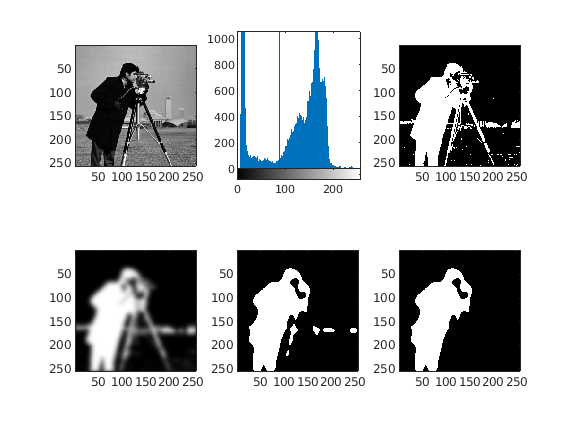

segmentation = zeros(size(msk));
segmentation(comps.PixelIdxList{1}) = 1; %only the largest object is set
subplot(2,3,6);
imagesc(segmentation);
axis tight equal;

## Creating Contour

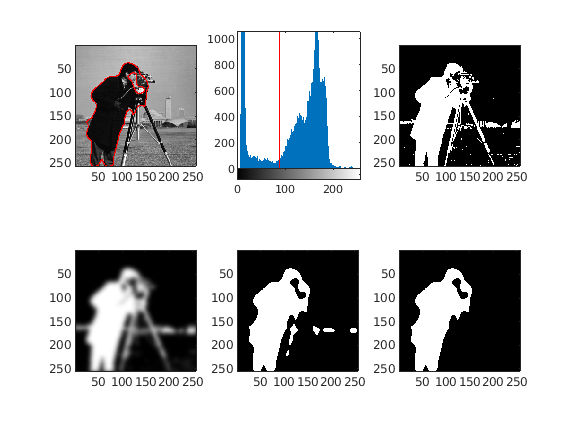

subplot(2,3,1);
hold on
contour(segmentation,[0.5,0.5],'r');
hold off;

## Canny Edge Detection Method in MATLAB

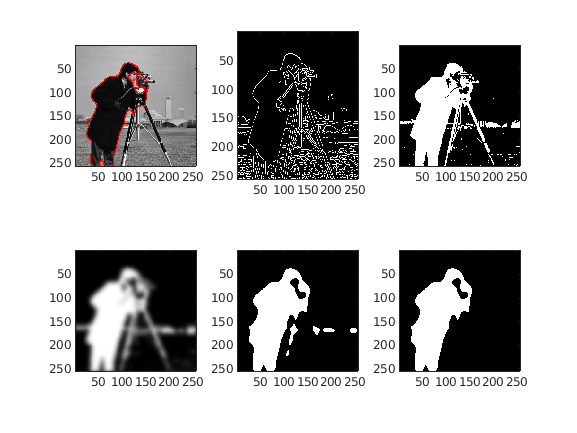

img_canny = edge(img,'canny');
subplot(2,3,2);
imagesc(img_canny);

# Segmentation for colored images

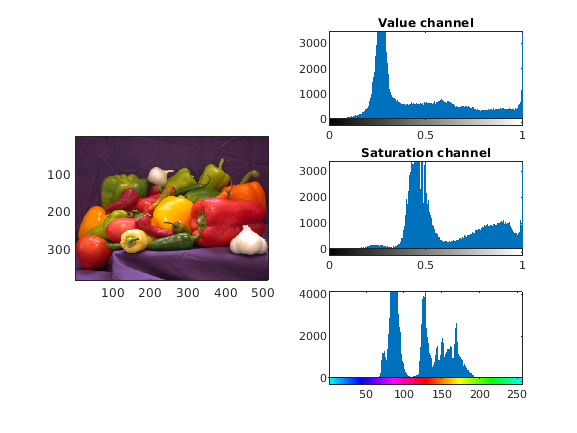

img = imread('peppers.png');
figure(2);
subplot(1,2,1);
imagesc(img);
axis tight equal;

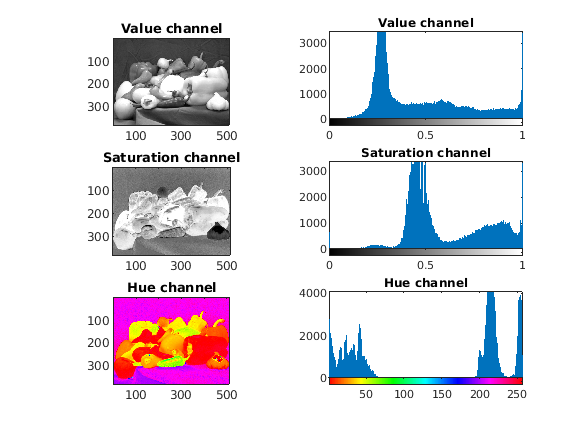

hsvfigure
hst = imhist((round(hsv(:,:,1)*255)+1),cmap);
thrsh1 = otsuthresh(hst);
%For circular histogram, 2 threshold are needed
%When we have an empty region of our histogram, the best thing to do is to translate
% our histogram values, such that the empty region corresponds to the lowest and 
% highest values.
h_shift = mod(0.5+hsv(:,:,1),1);
figure(3);

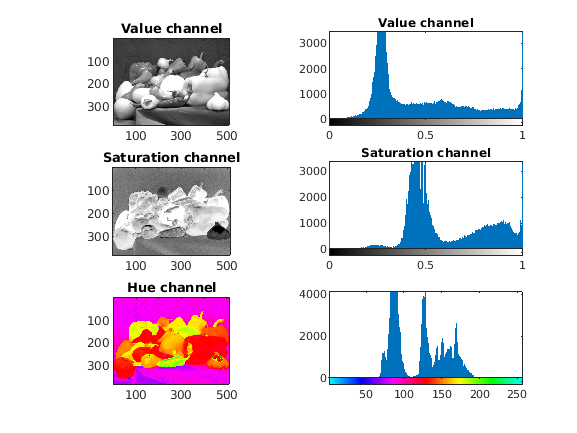

imhist(round(h_shift*255)+1,[cmap(128:end,:);cmap(1:127,:)]);
hst = imhist(round(h_shift*255)+1,[cmap(128:end,:);cmap(1:127,:)]);
thrsh2 = otsuthresh(hst)+0.5;
%background mask
back = hsv(:,:,1) >= thrsh1 & hsv(:,:,1) < thrsh2;
fore = ~back;
figure(2);

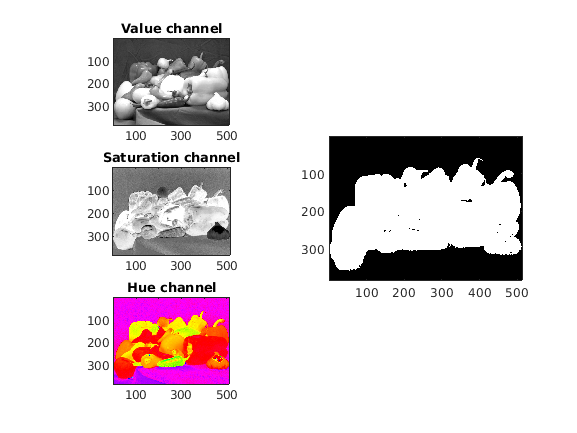

subplot(1,2,2);
imagesc(fore);
axis tight equal;